clear classes

clear all
clc
close all
rng(213);
datasets = {'cora', 'citeseer', 'webkb'};
processing_data_id = 3;
k = 10;         % kfold parameter

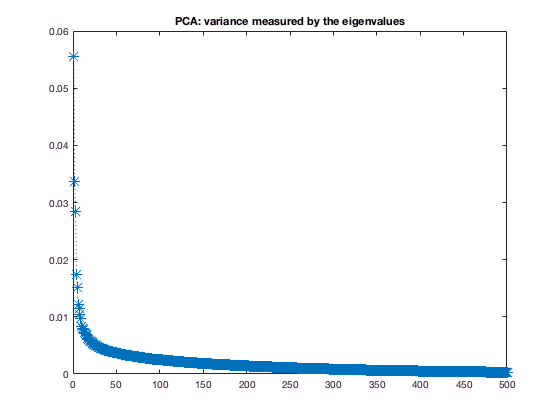

load([datasets{processing_data_id} '.mat']);
[M, ~] = size(X);
NN = size(I,1);
C = sparse(I(:,1), I(:,2), ones(NN,1), M, M);

CVO = cvpartition(M, 'KFold', k);
Y = preprocessing(X, 500, 'PCA');

for i = 1
    trIdx = CVO.training(i);
    teIdx = CVO.test(i);
    
    trC =  C(trIdx, trIdx);
    trY = Y(trIdx, :);
    [trRowIdx, trColumnIdx] = find(trC);
    
    tr_indexes = find(trIdx);
    Lia = ismember(I, tr_indexes);
    trI_indicator = logical(prod(Lia,2));
    teI = I(~trI_indicator, :);
end

save(['processed_' datasets{processing_data_id} '.mat'], 'trRowIdx', ...
    'trColumnIdx', 'trC', 'teI', 'trY', 'Y');